## **Problem 4**

**One of the simplest conjugated polymers is polyacetylene, whose structure is shown below. The double bonds are known to be slightly shorter than the single bonds (this phenomenon is called dimerization). Polyacetylene can be modeled as a solid with a onedimensional Bravais lattice along the x-axis.**

**a) What is the lattice period (from the picture)?**

c, not $d_1 + d_2$

**b) What are the atoms that constitute the basis? (The basis—a periodically repeated unit—is called a monomer in the case of polymeric chains). The hydrogen atom contributes to bonding with one electron in its 1s orbital, while C is in group 4, and contributes with 4 electrons distributed over its 2s and 2p orbitals (a total of 4 orbitals).**

Drawing attached

**c) How many bands will form? When the chain is formed, carbon’s 2s orbital and two of its three 2p orbitals form the bonds C-C and C-H that are located in the plane of the picture (the so-called sigma -bonds). In addition, each of the carbon atoms has an extra pz orbital, perpendicular to the plane of the paper, which overlap sideways and form the weaker pi bond.**

The pz orbital is what contributes to these bands, so two bands will form, one from each pz orbital from the two carbon atoms per basis.

**d) Assuming that two of the bands are formed by the carbon pz orbitals alone, use a simple nearest-neighbor tight-binding model to calculate the bandstructure of these two bands. Also, plot the calculated bandstructure within the first Brillouin zone.**

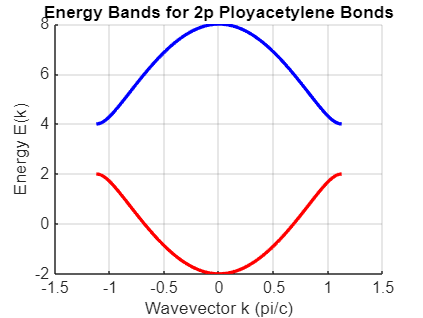

clc
clear
close all

% We can model this as 1D even though the carbons bond at an angle,
% so we can approximate c = d1 + d2

Ep = 3;
gamma_1 = -2;
gamma_2 = -3;
d1 = 1.5;
d2 = 1.3;
c = d1 + d2;

k = linspace(-pi/c, pi/c, 100); % really -pi/c to pi/c, but we have c in our cosine,
                           % so it cancels out

E_plus = Ep + sqrt(gamma_1^2 + gamma_2^2 + 2 * gamma_2 * gamma_1 * cos(k * c));
E_minus = Ep - sqrt(gamma_1^2 + gamma_2^2 + 2 * gamma_2 * gamma_1 * cos(k * c));

hold on;
grid on;
plot(k, E_plus, 'b', 'LineWidth', 2); % Upper band
plot(k, E_minus, 'r', 'LineWidth', 2); % Lower band
title("Energy Bands for 2p Ployacetylene Bonds");
xlabel('Wavevector k (pi/c)');
ylabel('Energy E(k)');